
H_BB = @(x,d) -x.*log2(x./(d-1)) - (1-x).*log2(1-x) ;
H_Bridge = @(x,d) -x.*log2(x) - ((1-x)).*log2((1-x)./d);
p2lambda = @(p,d) p.*(d-1)./d;
p_sift = @(p,d) (((d-1)/d).*p + d-1)./(d+1);

prot = Bridge5D; 
D = 5;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;


figure
hold on
x = q;
x = dps;
plot(x,qd ./ sift_vec,'ro--','DisplayName','H(Z_A|E)')

plot(x,(qd)./ sift_vec - H_Bridge(q,D) ,'mo--','DisplayName','key rate')

% plot(q,H_3(error./sift_vec /2).*sift_vec,'g-')
% plot(dps,qd - qB,'ro','DisplayName','H(Z_A|E)')
plot(x,H_Bridge(q,D),'go--','DisplayName','error correction')

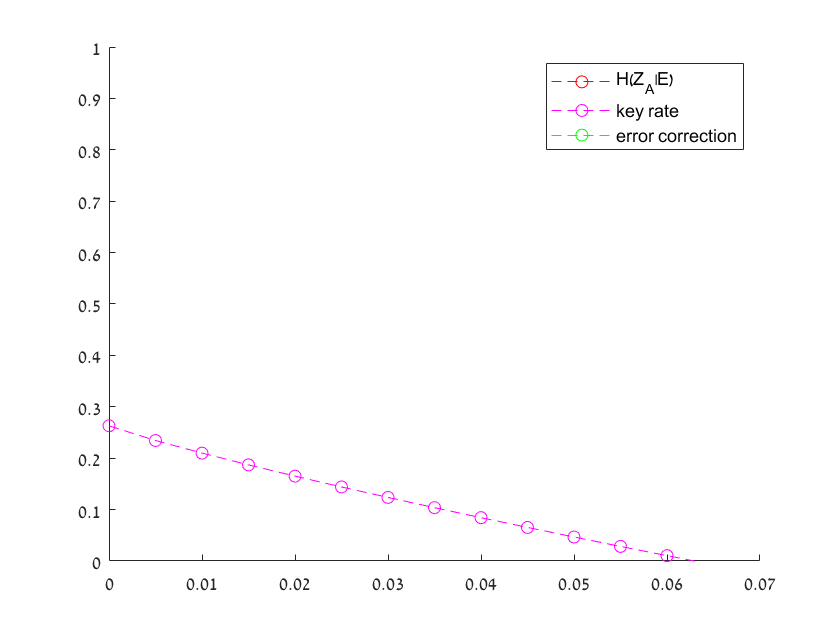

% plot(q,qB./ sift_vec,'ro','DisplayName','H(A|B)')
ylim([0 1])
legend


% save
S_each = 0

S_each = 0

S = 0

S = 0

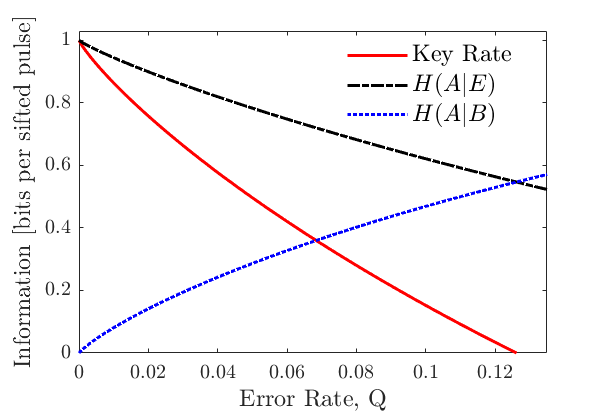

prot = BB2D; 
D = 2;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_BB(q+eps,D) ,'r-','LineWidth',1.5)
plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)
plot(x,H_BB(q+eps,D),'b:','LineWidth',1.5)
ylim([0 1.03])
xlim([0 0.135])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';

if S_each
    saveas(f,'BB_2.svg');
    saveas(f,'BB_2.png');
end

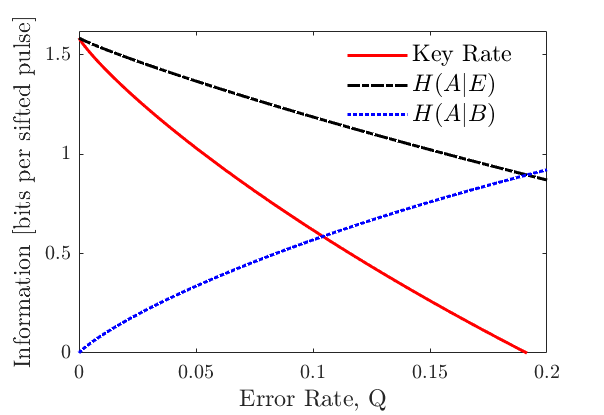

prot = BB3D;
D = 3;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_BB(q+eps,D) ,'r-','LineWidth',1.5)
plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)
plot(x,H_BB(q+eps,D),'b:','LineWidth',1.5)
ylim([0 1.62])
xlim([0 0.2])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';

if S_each
    saveas(f,'BB_3.svg');
    saveas(f,'BB_3.png');
end

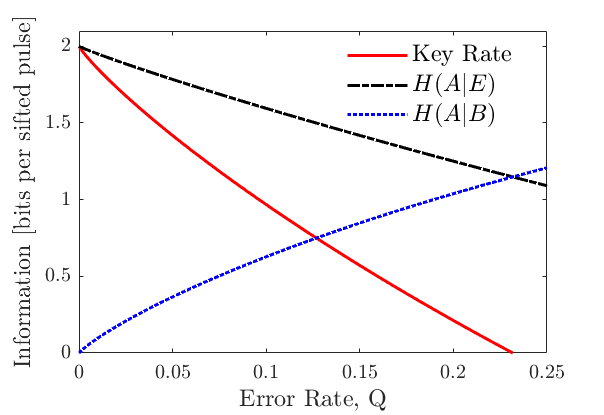

prot = BB4D; 
D = 4;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_BB(q+eps,D) ,'r-','LineWidth',1.5)
plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)
plot(x,H_BB(q+eps,D),'b:','LineWidth',1.5)
ylim([0 2.1])
xlim([0 0.25])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';


if S_each
    saveas(f,'BB_4.svg');
    saveas(f,'BB_4.png');
end

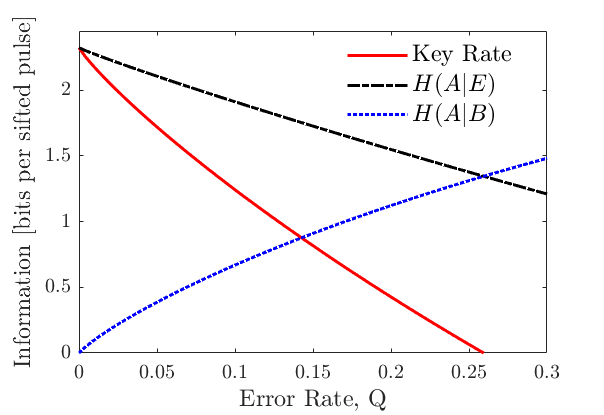

prot = BB5D; 
D = 5;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_BB(q+eps,D) ,'r-','LineWidth',1.5)
plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)
plot(x,H_BB(q+eps,D),'b:','LineWidth',1.5)
ylim([0 2.45])
xlim([0 0.3])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';


if S_each
    saveas(f,'BB_5.svg');
    saveas(f,'BB_5.png');
end

prot = Bridge2D; 
D = 2;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_Bridge(q,D) ,'r-','LineWidth',1.5)

plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)

plot(x,H_Bridge(q,D),'b:','LineWidth',1.5)

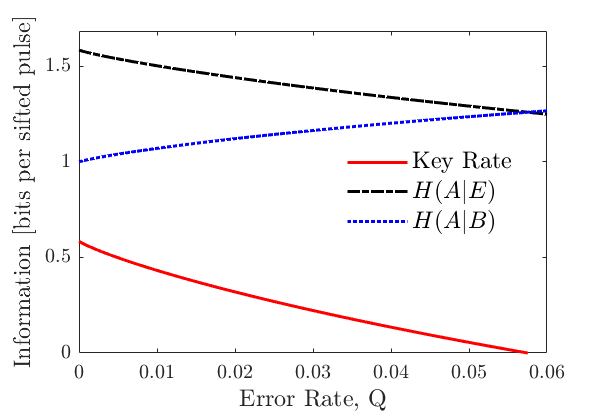

ylim([0 log2(D+1)+0.1])
xlim([0 0.06])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';

if S_each
    saveas(f,'Bridge_2.svg');
    saveas(f,'Bridge_2.png');
end

prot = Bridge3D; 
D = 3;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_Bridge(q,D) ,'r-','LineWidth',1.5)

plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)

plot(x,H_Bridge(q,D),'b:','LineWidth',1.5)

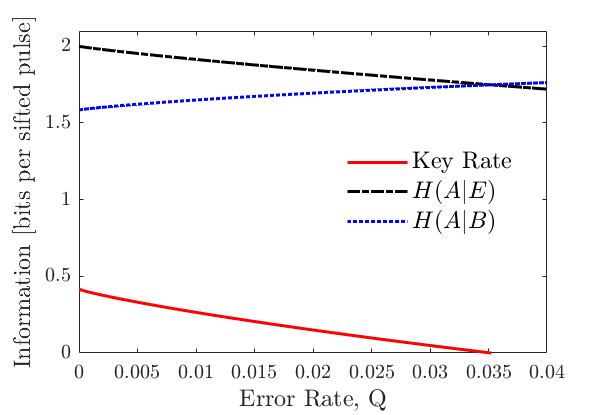

ylim([0 log2(D+1)+0.1])
xlim([0 0.04])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';


if S_each
    saveas(f,'Bridge_3.svg');
    saveas(f,'Bridge_3.png');
end

prot = Bridge4D; 
D = 4;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_Bridge(q,D) ,'r-','LineWidth',1.5)

plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)

plot(x,H_Bridge(q,D),'b:','LineWidth',1.5)

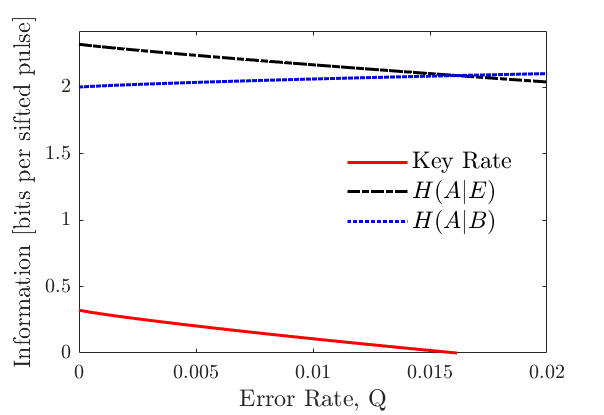

ylim([0 log2(D+1)+0.1])
xlim([0 0.02])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';

if S_each
    saveas(f,'Bridge_4.svg');
    saveas(f,'Bridge_4.png');
end

prot = Bridge5D; 
D = 5;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(x,(qd)./ sift_vec - H_Bridge(q,D) ,'r-','LineWidth',1.5)

plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5)

plot(x,H_Bridge(q,D),'b:','LineWidth',1.5)

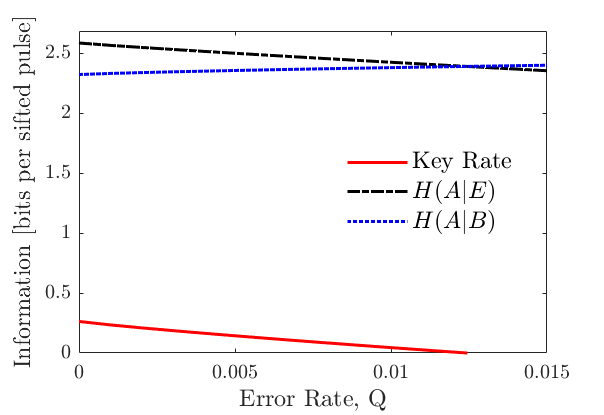

ylim([0 log2(D+1)+0.1])
xlim([0 0.015])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('Key Rate','$H(A|E)$','$H(A|B)$','Interpreter','latex','FontSize', 12);
legend('Location','best')
f.CurrentAxes.TickLabelInterpreter = 'latex';

if S_each
    saveas(f,'Bridge_5.svg');
    saveas(f,'Bridge_5.png');
end

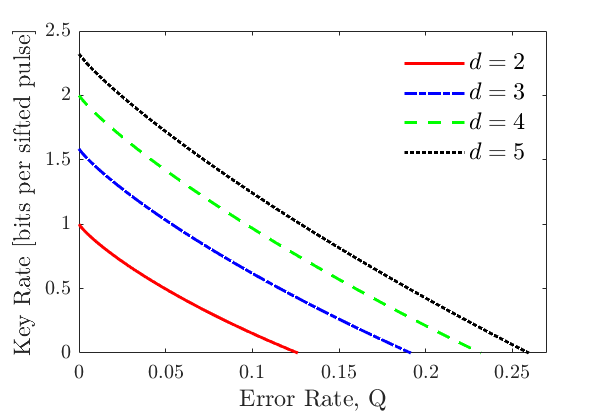

% BB Q
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(BB2D.q,(BB2D.qd)./ BB2D.sift_vec - H_BB(BB2D.q+eps,2) ,'r-','LineWidth',1.5)
plot(BB3D.q,(BB3D.qd)./ BB3D.sift_vec - H_BB(BB3D.q+eps,3) ,'b-.','LineWidth',1.5)
plot(BB4D.q,(BB4D.qd)./ BB4D.sift_vec - H_BB(BB4D.q+eps,4) ,'g--','LineWidth',1.5)
plot(BB5D.q,(BB5D.qd)./ BB5D.sift_vec - H_BB(BB5D.q+eps,5) ,'k:','LineWidth',1.5)
ylim([0 2.5])
xlim([0 0.27])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'BB_Q_sift.svg');
    saveas(f,'BB_Q_sift.png');
end

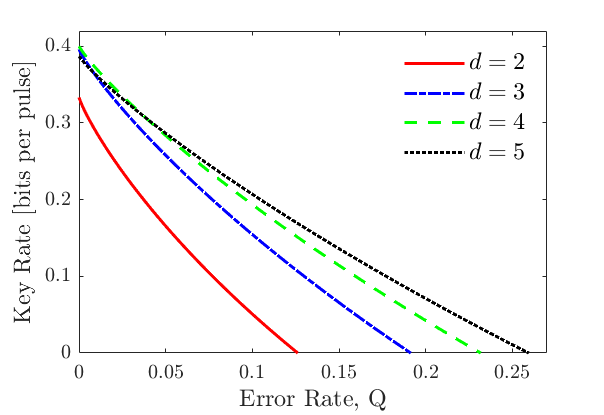


% --- sift ---
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(BB2D.q,((BB2D.qd)./ BB2D.sift_vec - H_BB(BB2D.q+eps,2))/3 ,'r-','LineWidth',1.5)
plot(BB3D.q,((BB3D.qd)./ BB3D.sift_vec - H_BB(BB3D.q+eps,3))/4 ,'b-.','LineWidth',1.5)
plot(BB4D.q,((BB4D.qd)./ BB4D.sift_vec - H_BB(BB4D.q+eps,4))/5 ,'g--','LineWidth',1.5)
plot(BB5D.q,((BB5D.qd)./ BB5D.sift_vec - H_BB(BB5D.q+eps,5))/6 ,'k:','LineWidth',1.5)
ylim([0 0.42])
xlim([0 0.27])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'BB_Q.svg');
    saveas(f,'BB_Q.png');
end

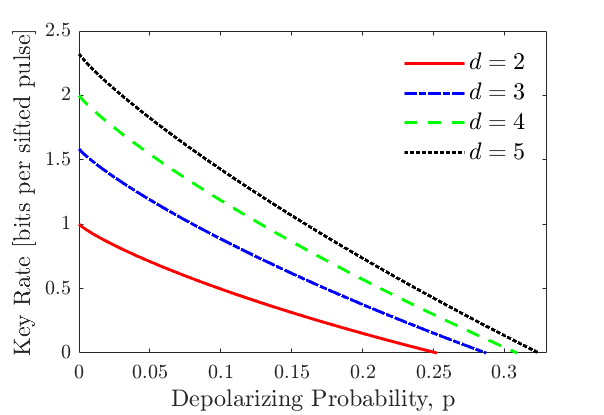

% BB p 
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(BB2D.dps,(BB2D.qd)./ BB2D.sift_vec - H_BB(BB2D.q+eps,2) ,'r-','LineWidth',1.5)
plot(BB3D.dps,(BB3D.qd)./ BB3D.sift_vec - H_BB(BB3D.q+eps,3) ,'b-.','LineWidth',1.5)
plot(BB4D.dps,(BB4D.qd)./ BB4D.sift_vec - H_BB(BB4D.q+eps,4) ,'g--','LineWidth',1.5)
plot(BB5D.dps,(BB5D.qd)./ BB5D.sift_vec - H_BB(BB5D.q+eps,5) ,'k:','LineWidth',1.5)
ylim([0 2.5])
xlim([0 0.33])
xlabel("Depolarizing Probability, p",'Interpreter','latex','FontSize', 12)
ylabel("Key Rate [bits per sifted pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'BB_p_sift.svg');
    saveas(f,'BB_p_sift.png');
end

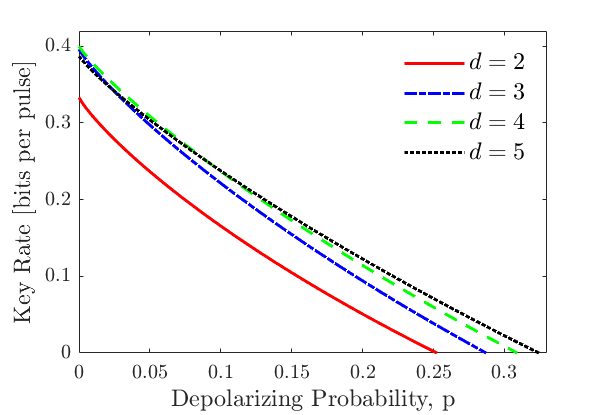


% --- sift ----
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(BB2D.dps,((BB2D.qd)./ BB2D.sift_vec - H_BB(BB2D.q+eps,2))/3 ,'r-','LineWidth',1.5)
plot(BB3D.dps,((BB3D.qd)./ BB3D.sift_vec - H_BB(BB3D.q+eps,3))/4 ,'b-.','LineWidth',1.5)
plot(BB4D.dps,((BB4D.qd)./ BB4D.sift_vec - H_BB(BB4D.q+eps,4))/5 ,'g--','LineWidth',1.5)
plot(BB5D.dps,((BB5D.qd)./ BB5D.sift_vec - H_BB(BB5D.q+eps,5))/6 ,'k:','LineWidth',1.5)
ylim([0 0.42])
xlim([0 0.33])
xlabel("Depolarizing Probability, p",'Interpreter','latex','FontSize', 12)
ylabel("Key Rate [bits per pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'BB_p.svg');
    saveas(f,'BB_p.png');
end

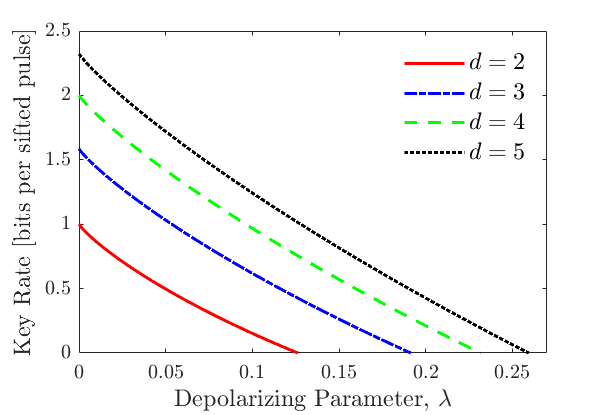

% BB lambda 
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(p2lambda(BB2D.dps,2),(BB2D.qd)./ BB2D.sift_vec - H_BB(BB2D.q+eps,2) ,'r-','LineWidth',1.5)
plot(p2lambda(BB3D.dps,3),(BB3D.qd)./ BB3D.sift_vec - H_BB(BB3D.q+eps,3) ,'b-.','LineWidth',1.5)
plot(p2lambda(BB4D.dps,4),(BB4D.qd)./ BB4D.sift_vec - H_BB(BB4D.q+eps,4) ,'g--','LineWidth',1.5)
plot(p2lambda(BB5D.dps,5),(BB5D.qd)./ BB5D.sift_vec - H_BB(BB5D.q+eps,5) ,'k:','LineWidth',1.5)
ylim([0 2.5])
xlim([0 0.27])
xlabel("Depolarizing Parameter, $\lambda$",'Interpreter','latex','FontSize', 12)
ylabel("Key Rate [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'BB_L_sift.svg');
    saveas(f,'BB_L_sift.png');
end

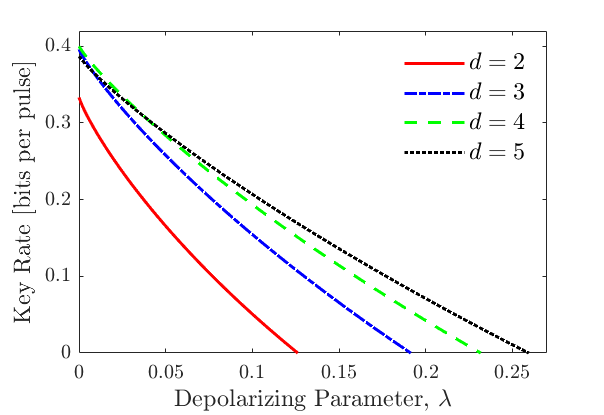


% --- sift 
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(p2lambda(BB2D.dps,2),((BB2D.qd)./ BB2D.sift_vec - H_BB(BB2D.q+eps,2))/3 ,'r-','LineWidth',1.5)
plot(p2lambda(BB3D.dps,3),((BB3D.qd)./ BB3D.sift_vec - H_BB(BB3D.q+eps,3))/4 ,'b-.','LineWidth',1.5)
plot(p2lambda(BB4D.dps,4),((BB4D.qd)./ BB4D.sift_vec - H_BB(BB4D.q+eps,4))/5 ,'g--','LineWidth',1.5)
plot(p2lambda(BB5D.dps,5),((BB5D.qd)./ BB5D.sift_vec - H_BB(BB5D.q+eps,5))/6 ,'k:','LineWidth',1.5)
ylim([0 0.42])
xlim([0 0.27])
xlabel("Depolarizing Parameter, $\lambda$",'Interpreter','latex','FontSize', 12)
ylabel("Key Rate [bits per pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'BB_L.svg');
    saveas(f,'BB_L.png');
end

% Bridge Q
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(Bridge2D.q,(Bridge2D.qd)./ Bridge2D.sift_vec - H_Bridge(Bridge2D.q,2) ,'r-','LineWidth',1.5)

plot(Bridge3D.q,(Bridge3D.qd)./ Bridge3D.sift_vec - H_Bridge(Bridge3D.q,3) ,'b-.','LineWidth',1.5)

plot(Bridge4D.q,(Bridge4D.qd)./ Bridge4D.sift_vec - H_Bridge(Bridge4D.q,4) ,'g--','LineWidth',1.5)

plot(Bridge5D.q,(Bridge5D.qd)./ Bridge5D.sift_vec - H_Bridge(Bridge5D.q,5) ,'k:','LineWidth',1.5)

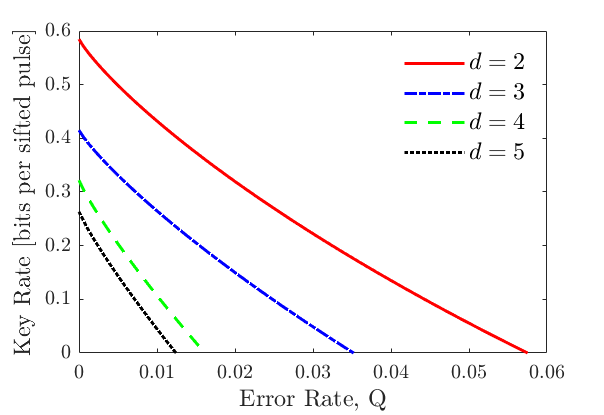

ylim([0 0.6])
xlim([0 0.06])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'Brigde_Q_sift.svg');
    saveas(f,'Bridge_Q_sift.png');
end

% sift
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(Bridge2D.q,((Bridge2D.qd)./ Bridge2D.sift_vec - H_Bridge(Bridge2D.q,2)).*p_sift(Bridge2D.dps,2) ,'r-','LineWidth',1.5)

plot(Bridge3D.q,((Bridge3D.qd)./ Bridge3D.sift_vec - H_Bridge(Bridge3D.q,3)).*p_sift(Bridge3D.dps,3) ,'b-.','LineWidth',1.5)

plot(Bridge4D.q,((Bridge4D.qd)./ Bridge4D.sift_vec - H_Bridge(Bridge4D.q,4)).*p_sift(Bridge4D.dps,4) ,'g--','LineWidth',1.5)

plot(Bridge5D.q,((Bridge5D.qd)./ Bridge5D.sift_vec - H_Bridge(Bridge5D.q,5)).*p_sift(Bridge5D.dps,5) ,'k:','LineWidth',1.5)

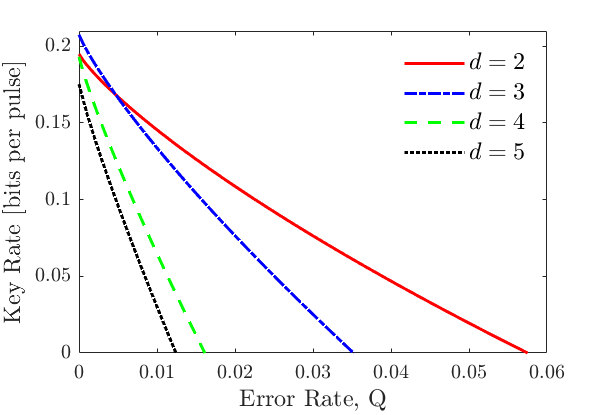

ylim([0 0.21])
xlim([0 0.06])
xlabel("Error Rate, Q",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'Brigde_Q.svg');
    saveas(f,'Bridge_Q.png');
end

% Bridge p
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(Bridge2D.dps,(Bridge2D.qd)./ Bridge2D.sift_vec - H_Bridge(Bridge2D.q,2) ,'r-','LineWidth',1.5)

plot(Bridge3D.dps,(Bridge3D.qd)./ Bridge3D.sift_vec - H_Bridge(Bridge3D.q,3) ,'b-.','LineWidth',1.5)

plot(Bridge4D.dps,(Bridge4D.qd)./ Bridge4D.sift_vec - H_Bridge(Bridge4D.q,4) ,'g--','LineWidth',1.5)

plot(Bridge5D.dps,(Bridge5D.qd)./ Bridge5D.sift_vec - H_Bridge(Bridge5D.q,5) ,'k:','LineWidth',1.5)

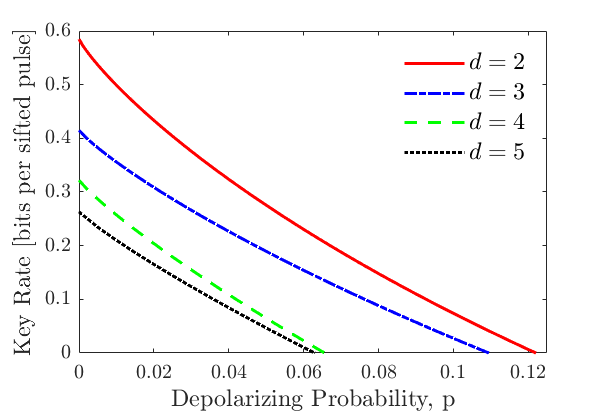

ylim([0 0.6])
xlim([0 0.125])
xlabel("Depolarizing Probability, p",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'Brigde_p_sift.svg');
    saveas(f,'Bridge_p_sift.png');
end


% --- sift
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(Bridge2D.dps,((Bridge2D.qd)./ Bridge2D.sift_vec - H_Bridge(Bridge2D.q,2)).*p_sift(Bridge2D.dps,2) ,'r-','LineWidth',1.5)

plot(Bridge3D.dps,((Bridge3D.qd)./ Bridge3D.sift_vec - H_Bridge(Bridge3D.q,3)).*p_sift(Bridge3D.dps,3) ,'b-.','LineWidth',1.5)

plot(Bridge4D.dps,((Bridge4D.qd)./ Bridge4D.sift_vec - H_Bridge(Bridge4D.q,4)).*p_sift(Bridge4D.dps,4) ,'g--','LineWidth',1.5)

plot(Bridge5D.dps,((Bridge5D.qd)./ Bridge5D.sift_vec - H_Bridge(Bridge5D.q,5)).*p_sift(Bridge5D.dps,5) ,'k:','LineWidth',1.5)

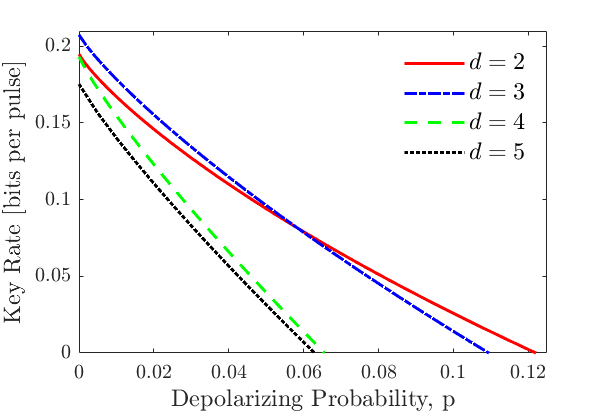

ylim([0 0.21])
xlim([0 0.125])
xlabel("Depolarizing Probability, p",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'Brigde_p.svg');
    saveas(f,'Bridge_p.png');
end

% Bridge lambda
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(p2lambda(Bridge2D.dps,2),(Bridge2D.qd)./ Bridge2D.sift_vec - H_Bridge(Bridge2D.q,2) ,'r-','LineWidth',1.5)

plot(p2lambda(Bridge3D.dps,3),(Bridge3D.qd)./ Bridge3D.sift_vec - H_Bridge(Bridge3D.q,3) ,'b-.','LineWidth',1.5)

plot(p2lambda(Bridge4D.dps,4),(Bridge4D.qd)./ Bridge4D.sift_vec - H_Bridge(Bridge4D.q,4) ,'g--','LineWidth',1.5)

plot(p2lambda(Bridge5D.dps,5),(Bridge5D.qd)./ Bridge5D.sift_vec - H_Bridge(Bridge5D.q,5) ,'k:','LineWidth',1.5)

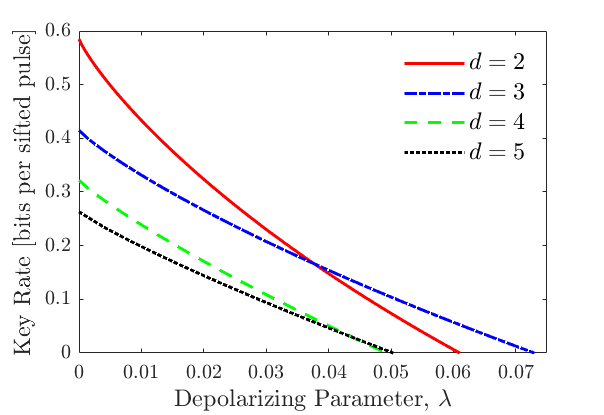

ylim([0 0.6])
xlim([0 0.075])
xlabel("Depolarizing Parameter, $\lambda$",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per sifted pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'Brigde_L_sift.svg');
    saveas(f,'Bridge_L_sift.png');
end


% sift
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[3.5 2.4];
hold on
plot(p2lambda(Bridge2D.dps,2),((Bridge2D.qd)./ Bridge2D.sift_vec - H_Bridge(Bridge2D.q,2)).*p_sift(Bridge2D.dps,2) ,'r-','LineWidth',1.5)

plot(p2lambda(Bridge3D.dps,3),((Bridge3D.qd)./ Bridge3D.sift_vec - H_Bridge(Bridge3D.q,3)).*p_sift(Bridge3D.dps,3) ,'b-.','LineWidth',1.5)

plot(p2lambda(Bridge4D.dps,4),((Bridge4D.qd)./ Bridge4D.sift_vec - H_Bridge(Bridge4D.q,4)).*p_sift(Bridge4D.dps,4) ,'g--','LineWidth',1.5)

plot(p2lambda(Bridge5D.dps,5),((Bridge5D.qd)./ Bridge5D.sift_vec - H_Bridge(Bridge5D.q,5)).*p_sift(Bridge5D.dps,5) ,'k:','LineWidth',1.5)

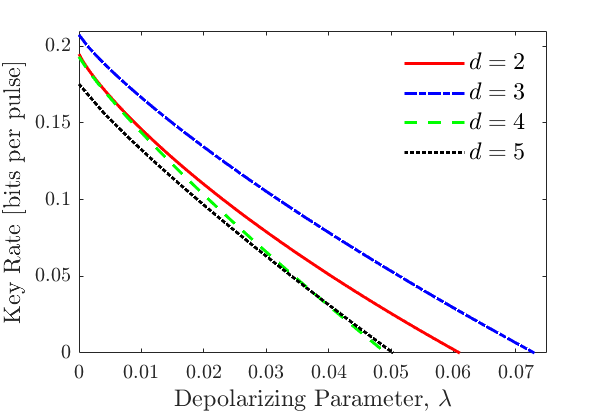

ylim([0 0.21])
xlim([0 0.075])
xlabel("Depolarizing Parameter, $\lambda$",'Interpreter','latex','FontSize', 12) 
ylabel("Key Rate [bits per pulse]",'Interpreter','latex','FontSize', 12) 
box on
legend('boxoff')
legend('$d = 2$','$d = 3$','$d = 4$','$d = 5$','Interpreter','latex','FontSize', 12);
f.CurrentAxes.TickLabelInterpreter = 'latex';
if S
    saveas(f,'Brigde_L.svg');
    saveas(f,'Bridge_L.png');
end